# Result 4: Similarity between individual task contrast and communities predict task performance

% Set project root
projectRoot = ''; 

% Load participant's task contrasts
load(fullfile(projectRoot, 'contrasts_tables.mat'))

% Load the first 500 columns from the Excel file
behav_data = readtable(fullfile(projectRoot, 'HCP_behaviouraldata.xlsx'));

behav_data = behav_data(:, 1:500);

behav_data_r = readtable(fullfile(projectRoot, 'behav_data_r.csv'));

% Get subject numbers from filenames
files = dir(fullfile(projectRoot, 'individual_tfmri_csv/output/*_FAoutput.rds'));
subject_numbers = erase({files.name}, '_FAoutput.rds');

% Filter behav_data to keep only matching subjects
behav_data = behav_data(ismember(string(behav_data.Subject), subject_numbers), :);

sub1_logic = readtable(fullfile(projectRoot, 'matching_sub1.csv'));
sub2_logic = readtable(fullfile(projectRoot, 'matching_sub2.csv'));

%unique family id based on both father and mother id
family_all_T = readtable(fullfile(projectRoot, 'family_vector_parentalID.csv'));% "family_vector_parentalID/family_vector_all"
family_all = family_all_T{:, 'ParentalID'};

% load avg g factor from cohort 1 in cifti order 
g = readtable(fullfile(projectRoot, 'g_avg_df.csv'));
g = g.Average_g';

## Specify which task contrast and centroid (uncomment):

target_contrast = 'W9'; %W9, R2, L2 which task contrast to correlate with centroid
comm_num = 4;  % Specify the comm centroid number

% target_contrast = 'R2'; %W9, R2, L2 which task contrast to correlate with centroid
% comm_num = 3;  % Specify the comm centroid number

## Create task contrast x community centroid correlations

% Preallocate the matrix to store the extracted column
numSubjects = length(contrasts_tables);
target_matrix = NaN(352, numSubjects); % Assuming numRows is already defined

% Loop through each subject and extract the column
for i = 1:numSubjects
    % Extract the target column from the current table
    if ismember(target_contrast, contrasts_tables{i}.Properties.VariableNames)
        target_matrix(:, i) = contrasts_tables{i}.(target_contrast);
    else
        warning('Subject %d does not have that column', i);
    end
end
target_matrix = target_matrix(1:347,:);

load('RDoC R01 aim2/comm_centroid1.mat'); %comm centroid1 is from sub1, specify centroid in next line
comms = [comm_centroid1; g];
target_comm = comms(comm_num,:)';

corr_coef = corr(target_matrix, target_comm, 'rows', 'complete');

% Preallocate a vector to store continuous Dice scores
dice_scores = NaN(1, size(target_matrix, 2));

% Loop through each column of target_matrix to calculate the continuous Dice score
for i = 1:size(target_matrix, 2)
    % Extract the current column from the target matrix
    current_column = target_matrix(:, i);
    
    % Calculate the intersection (element-wise product) and the sum of both vectors
    intersection = sum(current_column .* target_comm);
    union = sum(current_column.^2) + sum(target_comm.^2);
    
    % Compute the continuous Dice score
    dice_scores(i) = (2 * intersection) / union;
end

## Specify to correlate with behavior score... (only load one as target_behav)

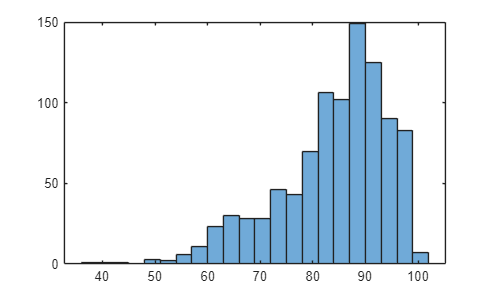

%WM_Task_2bk_Acc, or Language_Task_Story_Acc, or Relational_Task_Rel_Acc
target_behav = behav_data.('WM_Task_2bk_Acc');
labely = 'WM Task Accuracy';
histogram(target_behav)


% % target_behav = behav_data.('Relational_Task_Rel_Acc');
% % labely = 'RL Task Accuracy';
% % histogram(target_behav)

## ... or correlate with factor scores

% wm_fscores = readtable(fullfile(projectRoot, 'wm_fscores.csv');
% rl_fscores = readtable(fullfile(projectRoot, 'rl_fscores.csv');
% lg_fscores = readtable(fullfile(projectRoot, 'lg_fscores.csv');
% 
% target_behav = table2array(wm_fscores);
% % target_behav = -target_behav; 
% labely = 'wm fscores'
% histogram(target_behav)

## ... or ASR scores

% % asr = table2array(readtable(fullfile(projectRoot, 'asr_total.csv'));
% % target_behav = asr;
% 
% asr_int = behav_data_r.ASR_Intr_T;
% asr_ext = behav_data_r.ASR_Extn_T;
% target_behav = asr_int;
% histogram(target_behav);
% 
% labely = 'ASR Internalizing T scores';

## Create separate lists for cohort 1 and 2

% Convert string cells to logical
sub1_mask = strcmp(table2array(sub1_logic), 'TRUE');
sub2_mask = strcmp(table2array(sub2_logic), 'TRUE');

% Apply masks for cohort 1 (sub1), 2 (sub2)
corr_coef_sub1 = corr_coef(sub1_mask);
dice_scores_sub1 = dice_scores(sub1_mask);
target_behav_sub1  = target_behav(sub1_mask);

corr_coef_sub2 = corr_coef(sub2_mask);
dice_scores_sub2 = dice_scores(sub2_mask);
target_behav_sub2  = target_behav(sub2_mask);

% Mixed effects model  
Family_sub1 = family_all(sub1_mask);
Family_sub2 = family_all(sub2_mask);

for i = 1:3
    if i == 1
        x1 = corr_coef;         x2 = dice_scores';     y1 = target_behav;     Family_i = family_all;
        suffix = 'all sub';
    elseif i == 2
        x1 = corr_coef_sub1;    x2 = dice_scores_sub1'; y1 = target_behav_sub1; Family_i = Family_sub1;
        suffix = 'sub1';
    elseif i == 3
        x1 = corr_coef_sub2;    x2 = dice_scores_sub2'; y1 = target_behav_sub2; Family_i = Family_sub2;
        suffix = 'sub2';
    end

    % Ensure column vectors
    x1 = x1(:); x2 = x2(:); y1 = y1(:); Family_i = Family_i(:);

    % Remove rows with NaNs in any variable (including Family)
    valid = ~isnan(x1) & ~isnan(x2) & ~isnan(y1) & ~isnan(Family_i);
    x1 = x1(valid); x2 = x2(valid); y1 = y1(valid); Family_i = Family_i(valid);

    % Helper to convert t to r-equivalent (approx.; uses model DFE)
    t_to_r = @(t,df) sign(t).*sqrt((t.^2)./(t.^2 + df));

    % LMM: Y ~ X1 + (1|Family)
    zx1 = zscore(x1); zy = zscore(y1);
    keep1 = abs(zx1) < 3 & abs(zy) < 3;
    T1 = table(zy(keep1), zx1(keep1), categorical(Family_i(keep1)), ...
               'VariableNames', {'Y','X','Family'});
    lme1 = fitlme(T1, 'Y ~ X + (1|Family)');
    c1 = lme1.Coefficients;
    rowX = strcmp(c1.Name,'X');
    beta1 = c1.Estimate(rowX); se1 = c1.SE(rowX); t1 = c1.tStat(rowX); p1 = c1.pValue(rowX);
    r1 = t_to_r(t1, lme1.DFE);
    fprintf('[%s] LMM Y~X1+(1|Family): beta=%.3f, SE=%.3f, t=%.2f, df=%.0f, p=%.3g, r≈%.3f\n', ...
            suffix, beta1, se1, t1, lme1.DFE, p1, r1);

    % LMM: Y ~ X2 + (1|Family)
    zx2 = zscore(x2); zy = zscore(y1); % reuse zy if unchanged
    keep2 = abs(zx2) < 3 & abs(zy) < 3;
    T2 = table(zy(keep2), zx2(keep2), categorical(Family_i(keep2)), ...
               'VariableNames', {'Y','X','Family'});
    lme2 = fitlme(T2, 'Y ~ X + (1|Family)');
    c2 = lme2.Coefficients;
    rowX = strcmp(c2.Name,'X');
    beta2 = c2.Estimate(rowX); se2 = c2.SE(rowX); t2 = c2.tStat(rowX); p2 = c2.pValue(rowX);
    r2 = t_to_r(t2, lme2.DFE);
    fprintf('[%s] LMM Y~X2+(1|Family): beta=%.3f, SE=%.3f, t=%.2f, df=%.0f, p=%.3g, r≈%.3f\n', ...
            suffix, beta2, se2, t2, lme2.DFE, p2, r2);
end

[all sub] LMM Y~X1+(1|Family): beta=0.115, SE=0.030, t=3.81, df=941, p=0.00015, r≈0.123


[all sub] LMM Y~X2+(1|Family): beta=0.174, SE=0.031, t=5.68, df=937, p=1.82e-08, r≈0.182


[sub1] LMM Y~X1+(1|Family): beta=0.142, SE=0.049, t=2.89, df=403, p=0.0041, r≈0.142


[sub1] LMM Y~X2+(1|Family): beta=0.246, SE=0.052, t=4.74, df=399, p=2.92e-06, r≈0.231


[sub2] LMM Y~X1+(1|Family): beta=0.029, SE=0.052, t=0.57, df=322, p=0.57, r≈0.032


[sub2] LMM Y~X2+(1|Family): beta=0.066, SE=0.052, t=1.28, df=322, p=0.2, r≈0.071


## Scatter plot

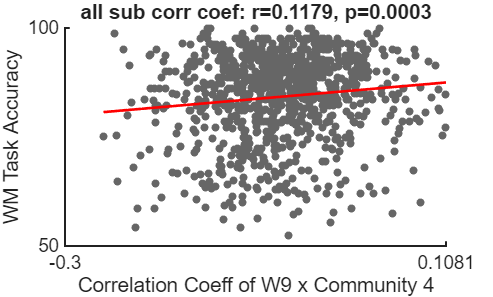

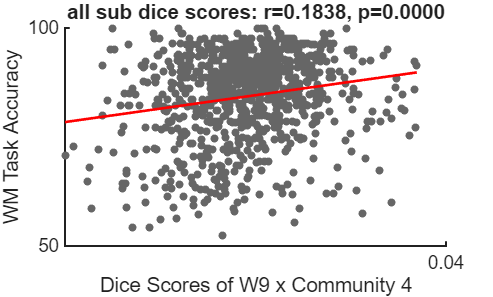

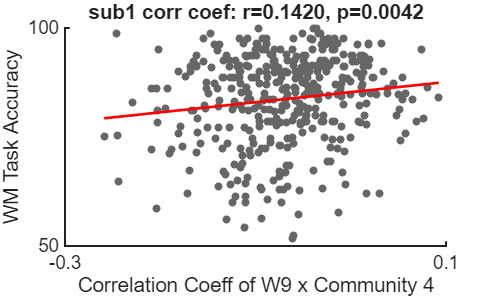

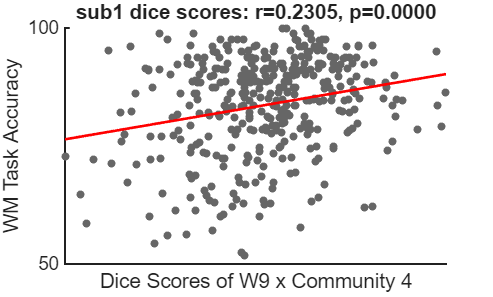

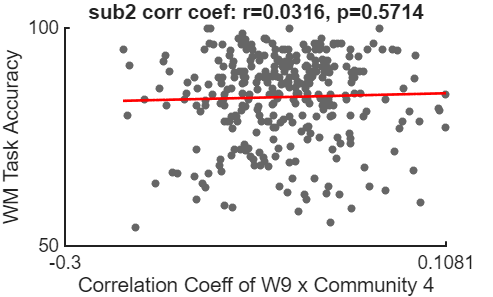

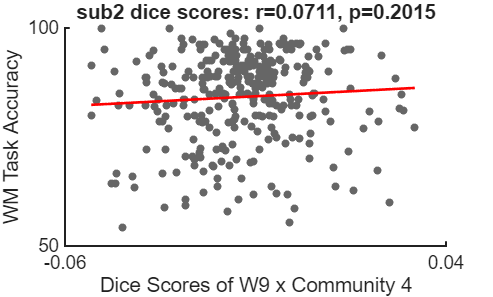

for i = 1:3
    if i == 1
        x1 = corr_coef;
        x2 = dice_scores';
        y1 = target_behav;
        suffix = 'all sub';
    elseif i == 2
        x1 = corr_coef_sub1;
        x2 = dice_scores_sub1';
        y1 = target_behav_sub1;
        suffix = 'sub1';
    elseif i == 3
        x1 = corr_coef_sub2;
        x2 = dice_scores_sub2';
        y1 = target_behav_sub2;
        suffix = 'sub2';
    end

    % Filter out NaNs first
    valid = ~isnan(x1) & ~isnan(x2) & ~isnan(y1);

    x1 = x1(valid);
    x2 = x2(valid);
    y1 = y1(valid);

    % Helper function for nice ticks
    pad = 0.05;  % 5% padding
    setlims = @(x) [min(x)-pad*range(x), max(x)+pad*range(x)];


    % CORR_COEF
    z_x1 = zscore(x1);
    z_y1 = zscore(y1);
    valid_idx = abs(z_x1) < 3 & abs(z_y1) < 3;
    x1_clean = x1(valid_idx);
    y1_clean = y1(valid_idx);

    [r, p] = corr(y1_clean, x1_clean, 'rows', 'complete');
    figure;
    scatter(x1_clean, y1_clean, 36, [0.4 0.4 0.4], 'filled');
    hold on;
    coeffs = polyfit(x1_clean, y1_clean, 1);
    x_fit = linspace(min(x1_clean), max(x1_clean), 100);
    y_fit = polyval(coeffs, x_fit);
    plot(x_fit, y_fit, 'r-', 'LineWidth', 2);
    title(sprintf('%s corr coef: r=%.4f, p=%.4f', suffix, r, p));
    xlabel(['Correlation Coeff of ' target_contrast ' x Community ' num2str(comm_num)]);
    ylabel(labely);

    set(gca, 'FontSize', 14, 'LineWidth', 1.5);
    % set(gca, 'FontSize', 14, 'LineWidth', 1.5, 'YDir', 'reverse');
    xlim('auto'); ylim('auto');
    xticks(xlim);
    yticks(ylim);
    % exportgraphics(gcf, fullfile(projectRoot, sprintf('figures/%s_corrcoef_rl.png', suffix)), 'Resolution', 300);
    hold off;

    % DICE_SCORES
    z_x2 = zscore(x2);
    z_y1 = zscore(y1);
    valid_idx = abs(z_x2) < 3 & abs(z_y1) < 3;
    x2_clean = x2(valid_idx);
    y1_clean = y1(valid_idx);

    [r, p] = corr(x2_clean, y1_clean, 'rows', 'complete');
    figure;
    scatter(x2_clean, y1_clean, 36, [0.4 0.4 0.4], 'filled');
    hold on;
    coeffs = polyfit(x2_clean, y1_clean, 1);
    x_fit = linspace(min(x2_clean), max(x2_clean), 100);
    y_fit = polyval(coeffs, x_fit);
    plot(x_fit, y_fit, 'r-', 'LineWidth', 2);
    title(sprintf('%s dice scores: r=%.4f, p=%.4f', suffix, r, p));
    xlabel(['Dice Scores of ' target_contrast ' x Community ' num2str(comm_num)]);
    ylabel(labely);

    set(gca, 'FontSize', 14, 'LineWidth', 1.5);
    % set(gca, 'FontSize', 14, 'LineWidth', 1.5, 'YDir', 'reverse');
    xlim('auto'); ylim('auto');
    xticks(xlim);
    yticks(ylim);
    % exportgraphics(gcf, fullfile(projectRoot, sprintf('figures/%s_dicescores_rl.png', suffix)), 'Resolution', 300);
    hold off;
end

## Functions

function [p_value, null_modularities] = testModularitySignificance(comm, modularity, n_iter, nodeTpMat, nodeBynode)
% testModularitySignificance - Assess significance of modularity against a null model
%
% Inputs:
%   comm        - Original community labels (e.g., color_indices)
%   modularity  - Observed modularity value from real data
%   n_iter      - Number of null iterations
%   nodeTpMat   - Matrix linking factors to maps (for computeProportionCategorical)
%   nodeBynode  - Adjacency matrix used in modularity calculation
%
% Outputs:
%   p_value            - Empirical one-tailed p-value
%   null_modularities  - Vector of null modularity values

    null_modularities = zeros(n_iter, 1);

    for i = 1:n_iter
        % Shuffle community labels
        shuffled_indices = comm(randperm(length(comm)));

        % Recalculate nodeComm based on shuffled community labels
        [shuffled_nodeComm, ~] = computeProportionCategorical(nodeTpMat, shuffled_indices);

        % Compute modularity for shuffled assignment
        null_modularities(i) = calMod(nodeBynode, shuffled_nodeComm);
    end

    % Calculate empirical p-value (one-tailed test)
    p_value = mean(null_modularities >= modularity);

    % Display results
    fprintf('Observed modularity: %.4f\n', modularity);
    fprintf('Empirical p-value: %.4f\n', p_value);

    % Plot null distribution
    figure('Color','w');
    histogram(null_modularities, 30, 'Normalization', 'pdf', ...
              'FaceColor', [0.6 0.6 0.6], 'EdgeColor', 'k', 'LineWidth', 1);
    hold on;
    xline(modularity, 'r-', 'LineWidth', 2);
    hold off;

    % Formatting for publication
    xlabel('Modularity', 'FontSize', 12);
    ylabel('Density', 'FontSize', 12);
    title('Null Distribution of Modularity', 'FontSize', 14);
    legend({'Null distribution', 'Observed modularity'}, 'FontSize', 10, 'Location', 'best');
    % xlim([min(null_modularities), 0.31]);


    % Styling axes only
    ax = gca;
    ax.Box = 'off';           % Remove top and right border
    ax.TickDir = 'out';       % Ticks outside
    ax.LineWidth = 1;         % Axis line width
    ax.FontSize = 10;
end